# Generation of Drive Unit Power Loss Map using FEM Charectrized PMSM 

Copyright 2022 - 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:open('ElectricVehicleDesignOverview.html')).

## **Generate Motor and Inverter Loss Map**

To model a permanent magnet synchronous motor (PMSM) inside a system level thermal simulation, you can generate a motor loss map and integrate it into the system level thermal blocks.

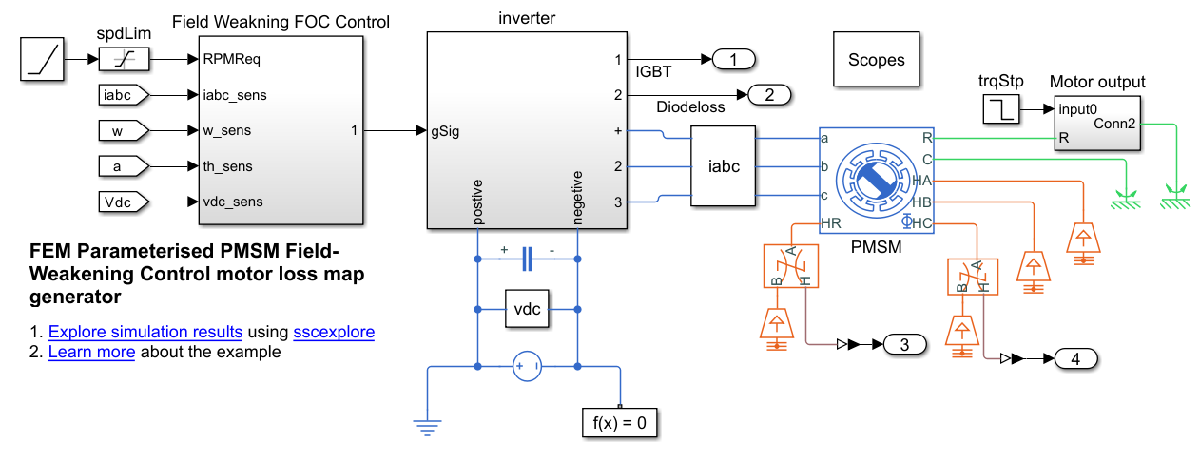

You define the torque speed and inverter junction temperature vectors for the loss map.To generate the motor and inverter loss map, run the `PMSMgetLoss()` function. This function runs the `PMSMfocControlLossMapGen` model for all values of `tqMa`, `tspMat` and `invJnTemp` . To change the parameters of the FEM-Parameterized PMSM in the model, use `PMSMSystemParams`. The function returns a cell array of motor and inverter loss maps. All the three input vectors are reduced to scalars for a quick demostration.

tqMat = [10];% Desired vector of torque Points N-m 
spMat= [500];% Desired vector of speed pionts RPM
invJnTemp = [298.15]; % Desired vector of IGBT and diode junction temperature K
maxMotorPower = 60000.00;% Watts Maximum allowed Motor Power. (Operating points with 
% Torque*Angular velocity above maxMotorPower will not run)
lossMatDU = getLossTable(tqMat,spMat,invJnTemp,maxMotorPower)

In this example, `PMSMmotorLossMap `and `PMSMinverterLossMap` store precomputed loss maps. Supply additional arguments 'overWriteMotLossMap' or 'overWriteInvLossMap' to the function `PMSMgetLoss()` inorder to replace the precomputed loss maps. Use this example code to replace the precomputed loss map :